# Algoritmos Numéricos por Computadora

# Tercer parcial - Otoño 2019

Cambia el nombre del script a NombreClaveúnica (ej: Marcelo123456).

Sube tu archivo resultado a comunidad $\to$ tercerParcial antes de las 10am.

Al correr tu script deben desplegarse los resultados.

## 1. Ecuación diferencial ordinaria de primer orden

Resuelve el siguiente problema de valor inicial en el intervalo de t=0 a t=2, donde y(0)=1. Grafica la solución $y\left(t\right)$.


$$\frac{\textrm{d}}{\textrm{d}t}y=yt^2 -1\ldotp 1y$$


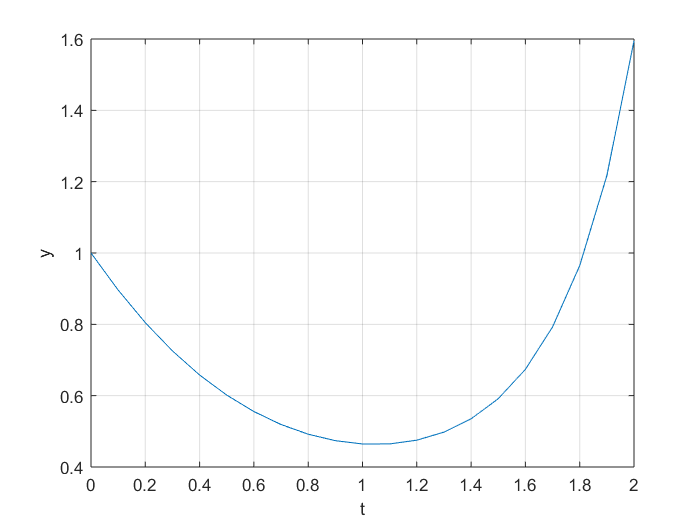

%
y0=1;
f= @(t,y) y*t^2-1.1*y;
h=0.1;
t0=0;
tf=2;
[t,y] = ivps(f,t0,y0,h,tf,'rk4');
plot(t,y)
xlabel('t');
ylabel('y');
grid on;

## 2. Sistema de dos ecuaciones diferenciales ordinarias de primer orden

Resuelve el siguiente sistema en el rango de x=0 a 0.4, con y(0)=2 y z(0)=4. Grafica la solución $y\left(t\right)\;$y $z\left(t\right)$.


$$\frac{\textrm{d}}{\textrm{d}t}y=-2y+5e^{-t}$$



$$\frac{\textrm{d}}{\textrm{d}t}z=-\frac{yz^2 }{2}$$


% 
f= @(t,yz) [-2*yz(1)+ 5*exp(-t); (-yz(1)*yz(2)^2)/2];
y0=[2;4];
t0=0;
tf=0.4;
[t,y] = ivps(f,t0,y0,0.1,tf,'rk4')

t =                    0   0.100000000000000   0.200000000000000   0.300000000000000   0.400000000000000


y =    2.000000000000000   2.067990661227379   2.082687107009738   2.057648591697272   2.003605509920199
   4.000000000000000   2.841761188263719   2.193791798331036   1.787394031597441   1.512621638165584


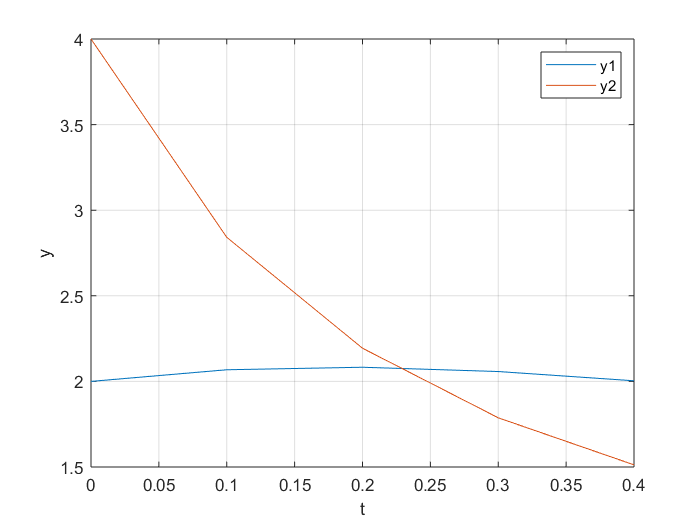

plot(t,y)
xlabel('t');
ylabel('y');
legend('y1','y2');
grid on;

## 3. Ecuación diferencial ordinaria de segundo orden

Resuelve el siguiente problema de t=0 a 5.


$$\frac{{\textrm{d}}^2 }{\textrm{d}t^2 }y+0\ldotp 6\;\frac{\textrm{d}}{\textrm{d}t}y+8y=0$$


donde y(0)=4 y y'(0)=0. Grafica la solución $y\left(t\right)$.

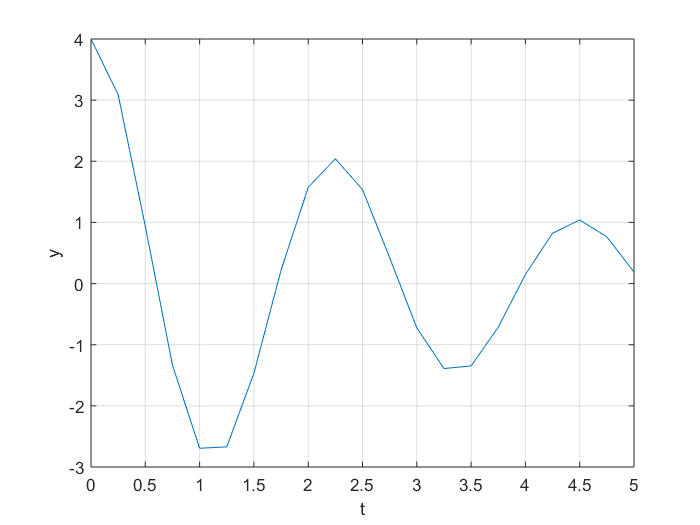

% 1ero despejar la 2da derivada 
% declarar una variable nueva  (d/dy que sea z) 
% y se queda como y, y'' como z' y y' como z
% y''= + 0.6y'+8y
%y'=z
%z'= -0.6z-8y
%yz(1,:)
f = @(t,yz) [yz(2); -0.6*yz(2)-8*yz(1)];
y0=[4;0];
t0=0;
tf=5;
[t,y] = ivps(f,t0,y0,0.25,tf,'rk4');
plot(t, y(1,:))
xlabel('t');
ylabel('y');
grid on;

## 4. Sistema masa - resortes con fricción

En el sistema de dos masas y tres resortes, existe ahora adicionalmente una fuerza de fricción sobre cada masa $F_i =-b\frac{\mathrm{d}}{\mathrm{d}t}x_i \;$. Considera que $b=0\ldotp 0125$ y resuelve el sistema amortiguado.

Calcula los valores propios de la matriz $M_d$. Determina el recíproco de la parte real de cada uno.  Encuentra el mayor valor (*dominant time constant*). Multiplica este valor por 4 y verifica que obtienes el tiempo que toma la respuesta en volverse aproximadamente cero.

%

m=0.05*ones(2,1);
k=0.01*ones(3,1);
b = 0.0125; %fricción

M=[-(k(1)+k(2))/m(1),k(2)/m(1);
    k(2)/m(2),-(k(2)+k(3))/m(2)];
Md=[zeros(2,2),eye(2);M,diag(-b./m)];

f=@ (t,xv) Md*xv;

TS=40;
np=100;
x0= 0.025;
xv0 = [x0;-x0; 0; 0];
[t,xv]=ivps(f,0,xv0,TS/np,TS,'rk4')

t =                    0   0.400000000000000   0.800000000000000   1.200000000000000   1.600000000000000   2.000000000000000   2.400000000000000   2.800000000000000   3.200000000000000   3.600000000000000   4.000000000000000   4.400000000000000   4.800000000000001   5.200000000000000   5.600000000000001   6.000000000000000   6.400000000000000   6.800000000000001   7.200000000000000   7.600000000000001   8.000000000000000   8.400000000000000   8.800000000000001   9.200000000000001   9.600000000000001  10.000000000000000  10.400000000000000  10.800000000000001  11.200000000000001  11.600000000000001  12.000000000000000  12.400000000000000  12.800000000000001  13.200000000000001  13.600000000000001  14.000000000000000  14.400000000000000  14.800000000000001  15.200000000000001  15.600000000000001  16.000000000000000  16.400000000000002  16.800000000000001  17.199999999999999  17.600000000000001  18.000000000000000  18.400000000000002  18.800000000000001  19.200000000000003  19.60000000000

xv =    0.025000000000000   0.023848600000000   0.020645688604900   0.015876678049747   0.010122711926857   0.003998896751452  -0.001904667459105  -0.007073980340245  -0.011110477573755  -0.013756164556176  -0.014903621072634  -0.014591409753344  -0.012986693046686  -0.010357850849752  -0.007040531392054  -0.003400836444045   0.000200750519130   0.003441495212794   0.006062065874532   0.007884000709939   0.008818185426336   0.008864427948597   0.008103015859082   0.006679784344087   0.004786665126817   0.002639908890399   0.000458175920098  -0.001557507168970  -0.003240285923565  -0.004469346559795  -0.005176483312165  -0.005347273866720  -0.005017269346875  -0.004264018408668  -0.003196044524958  -0.001940065158519  -0.000627778230729   0.000616545595516   0.001686617150687   0.002502049471643   0.003013177803393   0.003202637120771   0.003083862708112   0.002696942404720   0.002102448326974   0.001373999239466   0.000590348304833  -0.000172241659733  -0.000846671851948  -0.0013802158

x=xv(1,:);
v=xv(2,:);
plot(t,x);
grid on;
hold on;
plot(t,v);

title('Positions')
legend('x1','x2');
 
 lambda = eig(Md)

lambda =  -0.125000000000000 + 0.764444242571033i
 -0.125000000000000 - 0.764444242571033i
 -0.125000000000000 + 0.429389100932942i
 -0.125000000000000 - 0.429389100932942i


 tau=-1./real(lambda);
 dtc = 4*max(tau)

dtc =     32


 pr= real(lambda(1))

pr =   -0.125000000000000


 maxi= x0*exp(pr*t)

maxi =    0.025000000000000   0.023780735612518   0.022620935450899   0.021517699410626   0.020468268826950   0.019470019576785   0.018520455517043   0.017617202242968   0.016758001150891   0.015940703790544   0.015163266492816   0.014423745259512   0.013720290902351   0.013051144419025   0.012414632594785   0.011809163818525   0.011233224102931   0.010685373298718   0.010164241493515   0.009668525586363   0.009196986029286   0.008748443727779   0.008321777092452   0.007915919234476   0.007529855297805   0.007162619921505   0.006813294825850   0.006481006516147   0.006164924098540   0.005864257202345   0.005578254003711   0.005306199345669   0.005047412949866   0.004801247715519   0.004567088101318   0.004344348586261   0.004132472205540   0.003930929157841   0.003739215480566   0.003556851789663   0.003383382080915   0.003218372589695   0.003061410706325   0.002912103944337   0.002770078959058   0.002634980614047   0.002506471093070   0.002384229055389   0.002267948832235   0.00215733

 mini =- x0*exp(pr*t)

mini =   -0.025000000000000  -0.023780735612518  -0.022620935450899  -0.021517699410626  -0.020468268826950  -0.019470019576785  -0.018520455517043  -0.017617202242968  -0.016758001150891  -0.015940703790544  -0.015163266492816  -0.014423745259512  -0.013720290902351  -0.013051144419025  -0.012414632594785  -0.011809163818525  -0.011233224102931  -0.010685373298718  -0.010164241493515  -0.009668525586363  -0.009196986029286  -0.008748443727779  -0.008321777092452  -0.007915919234476  -0.007529855297805  -0.007162619921505  -0.006813294825850  -0.006481006516147  -0.006164924098540  -0.005864257202345  -0.005578254003711  -0.005306199345669  -0.005047412949866  -0.004801247715519  -0.004567088101318  -0.004344348586261  -0.004132472205540  -0.003930929157841  -0.003739215480566  -0.003556851789663  -0.003383382080915  -0.003218372589695  -0.003061410706325  -0.002912103944337  -0.002770078959058  -0.002634980614047  -0.002506471093070  -0.002384229055389  -0.002267948832235  -0.00215733

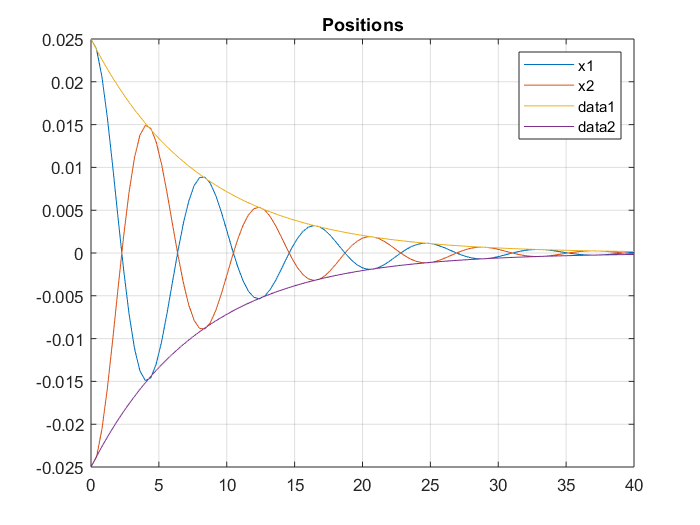

 plot(t,maxi) 
 plot(t,mini)
 hold off;

## 5. Problema con valores en la frontera

Grafica la solución $y\left(t\right)\;$de $7\frac{{\textrm{d}}^2 }{\textrm{d}t^2 }y-2\frac{\textrm{d}}{\textrm{d}t}y-y+t=0$ con las condiciones de frontera $y\left(0\right)=5$ y$y\left(20\right)=8$.

(Hint: Verifica que$\;y^' \left(0\right)$ está entre -1 y -0.5).

% 
f = @(t,yz) [yz(2); (2*yz(2)+yz(1)- t)/7];
a=0;
b=20;
ya=5;
yb=8;
h=0.01;
d = shooting(f,a,b,ya,yb,h,-1)

d =     -1.194201290832161e+04


d = shooting(f,a,b,ya,yb,h,-0.5)

d =      2.288881506469060e+04


g = @(s) shooting(f,a,b,ya,yb,h,s);
g(-1)

ans =     -1.194201290832161e+04


g(-0.5)

ans =      2.288881506469060e+04


[s, i] = biseccion(g,-1,-0.5);
y0= [ya;s]

y0 =    5.000000000000000
  -0.828571216889036


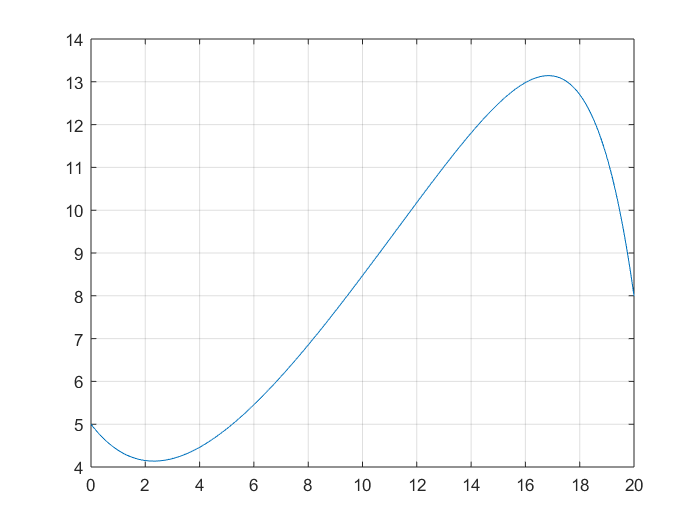

[t,y] = ivps(f,a,y0,h,b,'rk4');
plot(t,y(1,:));
grid on;

function [t,y] = ivps(f,t0,y0,h,tf,metodo)
 %solucionador de problemas con valor inicial
 % y' = f(t,y)   y(0)=y0
 
    switch metodo
        case 'euler'
            solver = @euler; 
            
        case 'midpoint'
            solver = @midpoint;
            
        case 'trapezoide'
            solver = @trapezoide; 
            
        case 'rk4'
            solver = @rk4; 
            
        otherwise
            error('Método desconocido');
    end
    
    t = t0:h:tf;
    y = zeros(length(y0),length(t));
    y(:,1) = y0;
    for i=1:1:length(t)-1
        y(:,i+1) = y(:,i) + solver(f,t(i),y(:,i),h)*h; 
    end

end

function phi= euler(f,t,y,~)
    phi = f(t,y);
end

function phi= midpoint(f,t,y,h)
    s1=f(t,y);
    ym= y + s1*(h/2);
    phi=f(t+h/2,ym);
end

function phi= trapezoide(f,t,y,h)
        s1=f(t,y);
        yf=y+h*s1;
        s2=f(t+h,yf);
        phi =(s1+s2)/2;     
end

function phi = rk4(f,t,y,h)
        s1 = f(t,y);
        s2 = f(t+h/2, y + (h/2)*s1);
        s3 = f(t+h/2, y + (h/2)*s2);
        s4 = f(t+h, y + h*s3);
        phi = (s1 + 2*s2 + 2*s3 + s4)/6;
end


function d = shooting(f,a,b,ya,yb,h,s)
%Regresa la distancia final aplicando el metodo IVPS.
% s es una adivinanza de f' en a

    y0 = [ya;s];
    [t,y] = ivps(f,a,y0,h,b,'rk4');
    yP = y(1,end);
    d=yP-yb;
end


